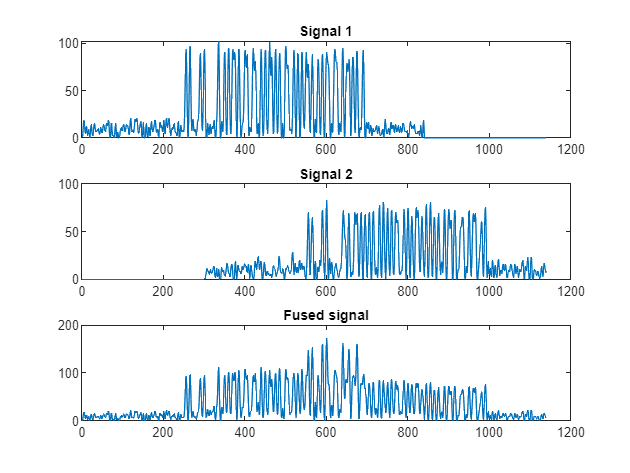

clear
load("ConvolutionArray.mat")


%Signals shorter for readability reasons
data_binary1 = [1 0 0 0 1 1 0 1 0 1 0 0]'; 
data_binary2 = [0 1 1 0 1 1 1 1 1 0 0 0]';
amplitude1 = 0.4;
amplitude2 = 0.3;
delay = 300;

packet_bits1 = GenerateBits(data_binary1);
packet_bits2 = GenerateBits(data_binary2);

[idealSignal1, ~, ~, ADCsignal1, ~] = GenerateSignal(packet_bits1, amplitude1);
[idealSignal2, ~, ~, ADCsignal2, ~] = GenerateSignal(packet_bits2, amplitude2);
ADCsignal1 = [ADCsignal1, zeros(1, delay)];
ADCsignal2 = [zeros(1, delay), ADCsignal2];
fused_signal = ADCsignal1 + ADCsignal2;

figure
subplot(3, 1, 1)
plot(ADCsignal1)
title("Signal 1")
subplot(3, 1, 2)
plot(ADCsignal2)
title("Signal 2")
subplot(3, 1, 3)
plot(fused_signal)
title("Fused signal")

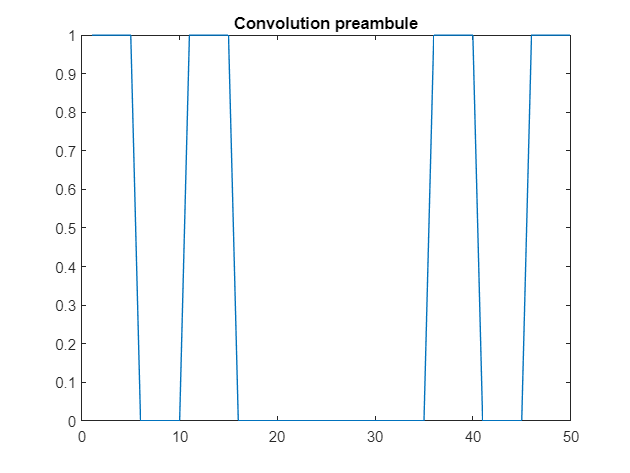

convIndex = 1; %Basic convolution

correlation1 = GenerateConv(ADCsignal1, convTypes(convIndex).convPreambule);
correlation2 = GenerateConv(ADCsignal2, convTypes(convIndex).convPreambule);
correlation_fused = GenerateConv(fused_signal, convTypes(convIndex).convPreambule);

target_point_1 = convTypes(convIndex).expectedMaximum;
target_point_2 = convTypes(convIndex).expectedMaximum + delay;

target_points_x = [target_point_1, target_point_2];
target_points_y = [correlation_fused(target_point_1), correlation_fused(target_point_2)];

figure
plot(convTypes(convIndex).convPreambule)
title("Convolution preambule")

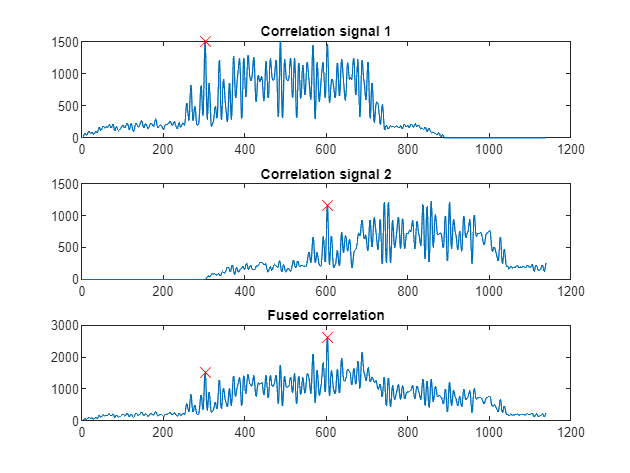


figure
subplot(3, 1, 1)
plot(correlation1)
hold on
scatter(target_point_1, correlation1(target_point_1),100, 'x','red', 'DisplayName', "Target hit")
title("Correlation signal 1")
hold off
subplot(3, 1, 2)
plot(correlation2)
hold on
scatter(target_point_2, correlation2(target_point_2),100, 'x','red', 'DisplayName', "Target hit")
title("Correlation signal 2")
hold off
subplot(3, 1, 3)
plot(correlation_fused)
hold on
scatter(target_points_x, target_points_y,100, 'x','red', 'DisplayName', "Target hit")
title("Fused correlation")
hold off

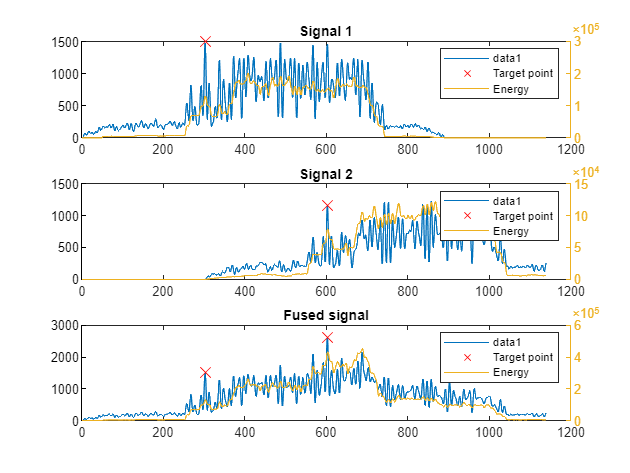

energy1 = GenerateEnergy(ADCsignal1, length(convTypes(convIndex).convPreambule));
energy2 = GenerateEnergy(ADCsignal2, length(convTypes(convIndex).convPreambule));
energy_fused = GenerateEnergy(fused_signal, length(convTypes(convIndex).convPreambule));

figure
subplot(3, 1, 1)
plot(correlation1)
hold on
scatter(target_point_1, correlation1(target_point_1),100, 'x','red', 'DisplayName', "Target point")
yyaxis right
plot(energy1, 'DisplayName', "Energy")
legend()
title("Signal 1")
hold off
subplot(3, 1, 2)
plot(correlation2)
hold on
scatter(target_point_2, correlation2(target_point_2),100, 'x','red', 'DisplayName', "Target point")
yyaxis right
plot(energy2, 'DisplayName', "Energy")
legend()
title("Signal 2")
hold off
subplot(3, 1, 3)
plot(correlation_fused)
hold on
scatter(target_points_x, target_points_y,100, 'x','red', 'DisplayName', "Target point")
yyaxis right
plot(energy_fused, 'DisplayName', "Energy")
legend()
title("Fused signal")
hold off

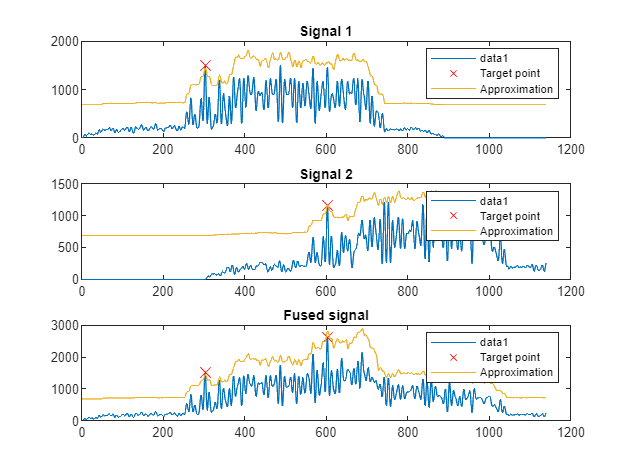

load("tempNeigiamasRodiklisData.mat", "allApproximations") %For approximation data

approx_index = 1; %Normal mean

approximation1 = GenerateApprox(energy1, allApproximations(approx_index));
approximation2 = GenerateApprox(energy2, allApproximations(approx_index));
approximation_fused = GenerateApprox(energy_fused, allApproximations(approx_index));

figure
subplot(3, 1, 1)
plot(correlation1)
hold on
scatter(target_point_1, correlation1(target_point_1),100, 'x','red', 'DisplayName', "Target point")
plot(approximation1, 'DisplayName', "Approximation")
legend()
title("Signal 1")
hold off
subplot(3, 1, 2)
plot(correlation2)
hold on
scatter(target_point_2, correlation2(target_point_2),100, 'x','red', 'DisplayName', "Target point")
plot(approximation2, 'DisplayName', "Approximation")
legend()
title("Signal 2")
hold off
subplot(3, 1, 3)
plot(correlation_fused)
hold on
scatter(target_points_x, target_points_y,100, 'x','red', 'DisplayName', "Target point")
plot(approximation_fused, 'DisplayName', "Approximation")
legend()
title("Fused signal")
hold off

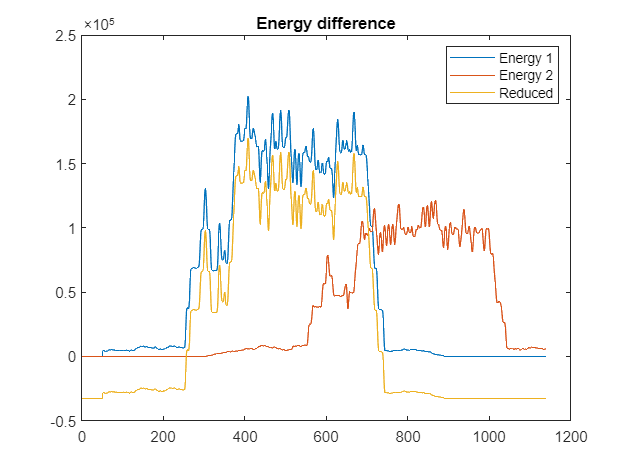

%Signal seperation attempts
preambule_energy1 = energy1(target_point_1)/4;

energy_reduced = energy1 - preambule_energy1;

%correlation1 = GenerateConv(ADCsignal1, convTypes(convIndex).convPreambule);
approximation_reduced = GenerateApprox(energy_reduced, allApproximations(approx_index));

figure
plot(energy1, 'DisplayName', "Energy 1")
hold on
plot(energy2, 'DisplayName', "Energy 2")
plot(energy_reduced, 'DisplayName', "Reduced")
legend
title("Energy difference")
hold off

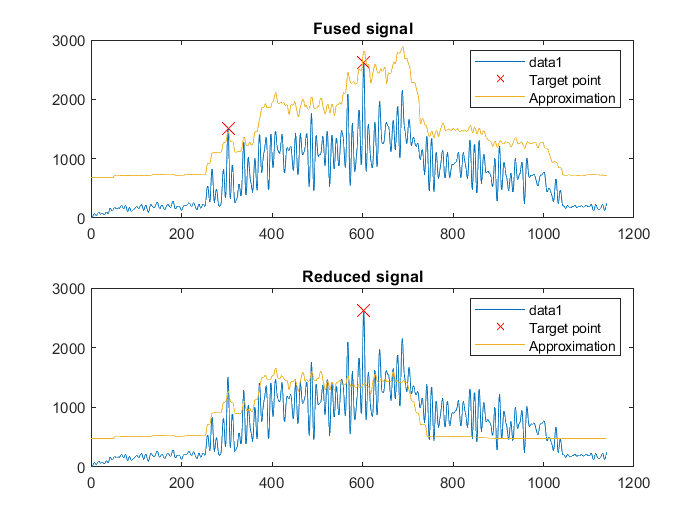


figure
subplot(2, 1, 1)
plot(correlation_fused)
hold on
scatter(target_points_x, target_points_y,100, 'x','red', 'DisplayName', "Target point")
plot(approximation_fused, 'DisplayName', "Approximation")
legend()
title("Fused signal")
hold off
subplot(2, 1, 2)
plot(correlation_fused)
hold on
scatter(target_point_2, correlation_fused(target_point_2),100, 'x','red', 'DisplayName', "Target point")
plot(approximation_reduced, 'DisplayName', "Approximation")
legend()
title("Reduced signal")
hold off

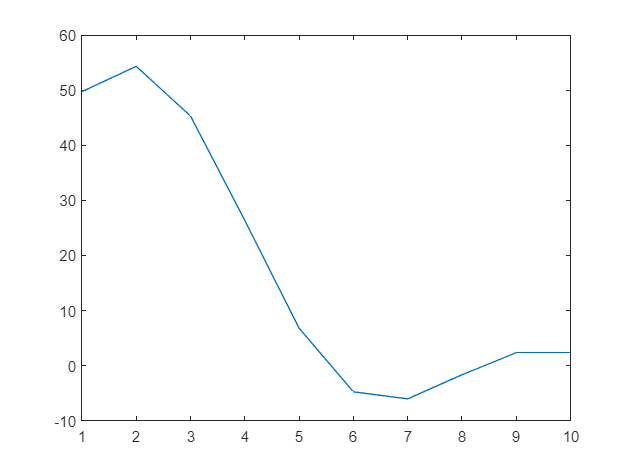

%signal deletion
fdiskret = 10E6;
tdiskret = 1/fdiskret;
tprescaler = 10;
idealOne = [ones(1, round(0.5E-6/tdiskret*tprescaler)), zeros(1, round(0.5E-6/tdiskret*tprescaler))];
idealZero = [zeros(1, round(0.5E-6/tdiskret*tprescaler)), ones(1, round(0.5E-6/tdiskret*tprescaler))]; %100ilgis

adc_signal_ampl = fused_signal(target_point_1-2)/2; %- because correlation is lagging or smth

load 'FiltroKoef.mat';

filteredOne = [idealOne, zeros(1, 50)];
filteredZero = [idealZero, ones(1, 50)];

filteredOne = filter(Hd, filteredOne)*adc_signal_ampl;
filteredZero = filter(Hd, filteredZero)*adc_signal_ampl;

filteredOne = filteredOne(41:10:(length(filteredOne)-10));
filteredZero = filteredZero(41:10:(length(filteredZero)-10));

figure
plot(filteredOne)

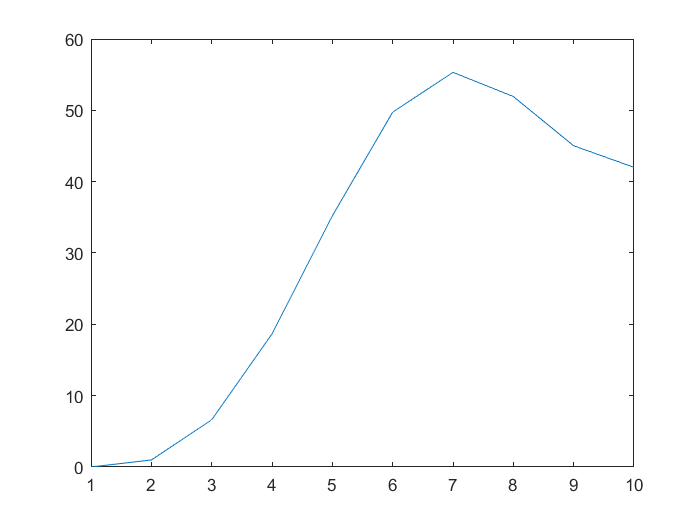

plot(filteredZero)

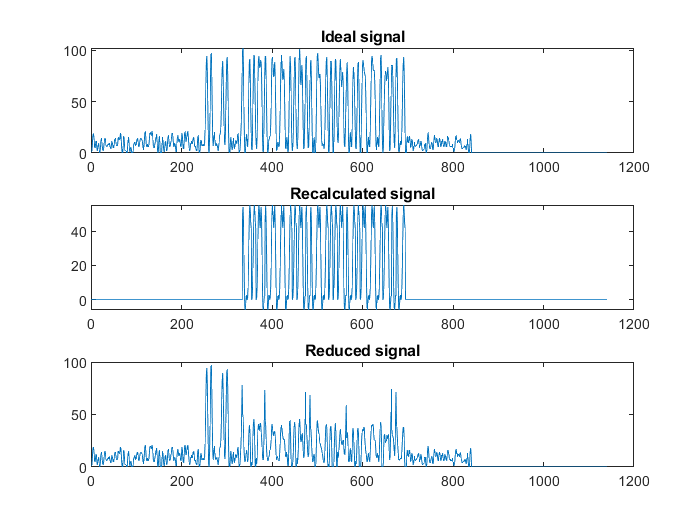


idealOne = idealOne(1:10:length(idealOne));
idealZero = idealZero(1:10:length(idealZero));


calculated_signal1 = zeros(1, length(fused_signal));
bit_idx = 1;
for i = (delay + convTypes(convIndex).convPreambule + 35 +length(idealOne)):length(idealOne):length(fused_signal)
    if bit_idx <= length(packet_bits1)
        if packet_bits1(1, bit_idx) == 0
            calculated_signal1((i - length(idealOne)) : i-1) = filteredZero;
            %fused_signal_reduced1((i - length(idealOne)+1) : i) = max(fused_signal((i - length(idealOne)+1) : i) - idealZero, 0);
        else
            calculated_signal1((i - length(idealOne)) : i-1) = filteredOne;
            %fused_signal_reduced1((i - length(idealOne)+1) : i) = max(fused_signal((i - length(idealOne)+1) : i) - idealOne, 0);
        end
        bit_idx = bit_idx + 1;
    end
end

fused_signal_reduced1 = max(fused_signal - calculated_signal1, 0); %Clamp signal to 0

figure
subplot(3, 1, 1)
plot(ADCsignal1)
title("Ideal signal")
hold off
subplot(3, 1, 2)
plot(calculated_signal1)
title("Recalculated signal")
hold off
subplot(3, 1, 3)
plot(max(ADCsignal1 - calculated_signal1, 0))
title("Reduced signal")

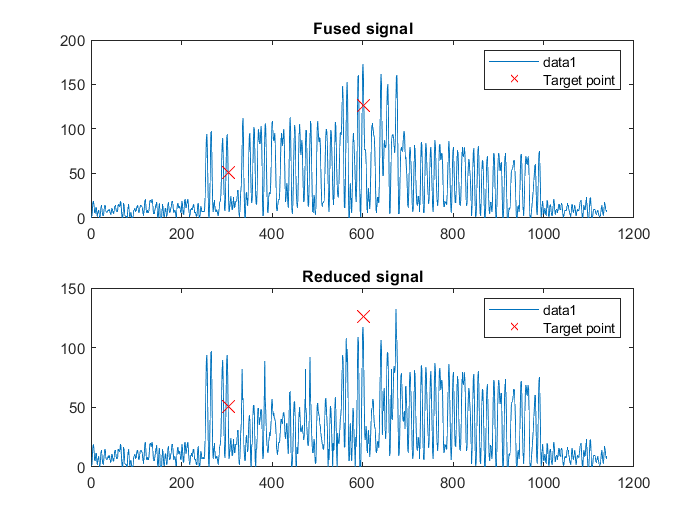


figure
subplot(2, 1, 1)
plot(fused_signal)
hold on
scatter(target_points_x, [fused_signal(target_point_1), fused_signal(target_point_2)],100, 'x','red', 'DisplayName', "Target point")
legend()
title("Fused signal")
hold off
subplot(2, 1, 2)
plot(fused_signal_reduced1)
hold on
scatter(target_points_x, [fused_signal(target_point_1), fused_signal(target_point_2)],100, 'x','red', 'DisplayName', "Target point")
legend()
title("Reduced signal")
hold off

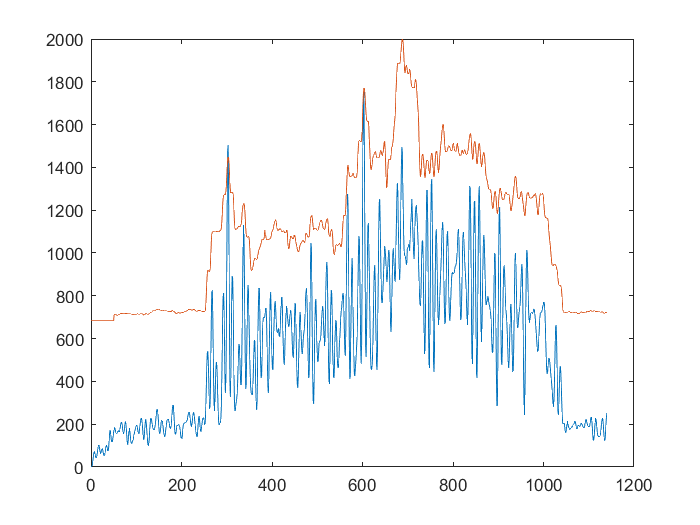

correlation_reduced = GenerateConv(fused_signal_reduced1, convTypes(convIndex).convPreambule);
energy_reduced = GenerateEnergy(fused_signal_reduced1, length(convTypes(convIndex).convPreambule));
approximation_reduced = GenerateApprox(energy_reduced, allApproximations(approx_index));

figure
plot(correlation_reduced, 'DisplayName', "Correlation")
hold on
plot(approximation_reduced, 'DisplayName', "Approximation")
hold off